# RRMCFigures

## First Scope

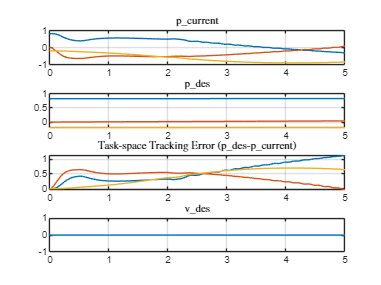

% robot = loadrobot('universalUR5', 'DataFormat', 'column')
figure;
subplot(4,1,1); 
plot(out.p_current.time, squeeze(out.p_current.signals.values)); 
title('p\_current', 'Interpreter', 'latex');
grid on;
subplot(4,1,2); 
plot(out.p_des.time, squeeze(out.p_des.signals.values)); 
title('p\_des', 'Interpreter', 'latex');
grid on;
subplot(4,1,3); 
plot(out.p_des_sub_p_current.time, squeeze(out.p_des_sub_p_current.signals.values)); 
title('Task-space Tracking Error (p\_des-p\_current)', 'Interpreter', 'latex');
grid on;
subplot(4,1,4); 
plot(out.v_des.time, squeeze(out.v_des.signals.values)); 
title('v\_des', 'Interpreter', 'latex');
grid on;

## Second Scope

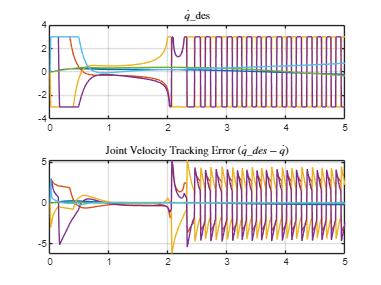

figure;
subplot(2,1,1); 
plot(out.q_dot_des.time, squeeze(out.q_dot_des.signals.values)); 
title('$\dot{q}$\_des', 'Interpreter', 'latex');
grid on;
subplot(2,1,2); 
plot(out.q_dot_des_sub_q_dot.time, squeeze(out.q_dot_des_sub_q_dot.signals.values)); 
title('Joint Velocity Tracking Error ($\dot{q}\_des - \dot{q}$)', 'Interpreter', 'latex');
grid on;

## Third Scope

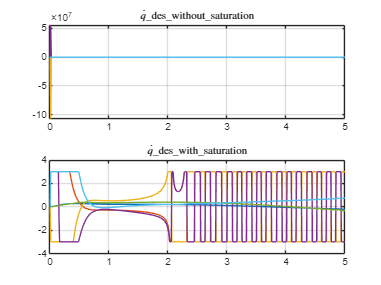

figure;
subplot(2,1,1); 
plot(out.q_dot_des_nosat.time, squeeze(out.q_dot_des_nosat.signals.values)); 
title('$\dot{q}$\_des\_without\_saturation', 'Interpreter', 'latex');
grid on;
subplot(2,1,2); 
plot(out.q_dot_des.time, squeeze(out.q_dot_des.signals.values)); 
title('$\dot{q}$\_des\_with\_saturation', 'Interpreter', 'latex');
grid on;

## Fourth Scope

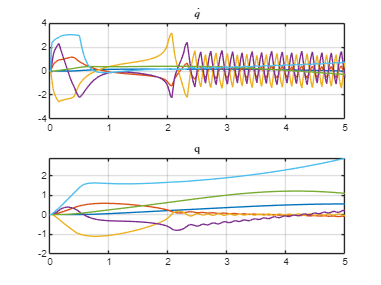

figure;
subplot(2,1,1);
plot(out.q_dot.time, squeeze(out.q_dot.signals.values)); 
title('$\dot{q}$', 'Interpreter', 'latex');
grid on;
subplot(2,1,2);
plot(out.q.time, squeeze(out.q.signals.values)); 
title('q', 'Interpreter', 'latex');
grid on;

## End-Effector Path Trackin

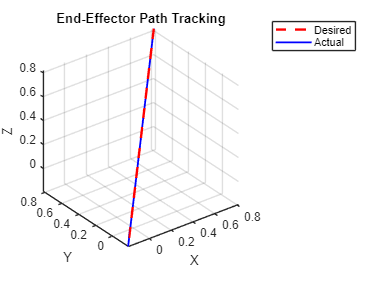


figure;
plot3(out.p_des.signals.values(:,1), out.p_des.signals.values(:,2), out.p_des.signals.values(:,3), 'r--', 'LineWidth',2); 
hold on;
plot3(out.p_current.signals.values(:,1), out.p_current.signals.values(:,2), out.p_current.signals.values(:,3), 'b', 'LineWidth',1.5);
legend('Desired', 'Actual');
xlabel('X'); 
ylabel('Y'); 
zlabel('Z'); 
title('End-Effector Path Tracking');
grid on; 
axis equal;

## Error Tracking

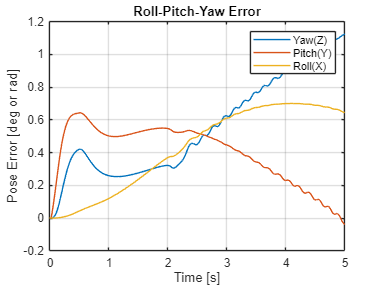


err = out.trvecsub.signals.values;
figure;
plot(out.trvecsub.time, squeeze(err)); 
xlabel('Time [s]');
ylabel('Pose Error [deg or rad]');
title('Roll-Pitch-Yaw Error');
legend('Yaw(Z)','Pitch(Y)','Roll(X)');
grid on;



maxErr = max(abs(err));
rmsErr = sqrt(mean(err.^2));
disp(['Max Error for each axis: ', num2str(maxErr)]);

Max Error for each axis: 0  1.8989e-06  7.3211e-06   0.0073826    0.026412    0.048292    0.071992     0.09712     0.12317     0.14988     0.17705     0.20452     0.23218     0.25988     0.28752     0.31496     0.34211     0.36846     0.39335     0.41674     0.43866     0.45911     0.47816     0.49582     0.51215     0.52719     0.54097     0.55356     0.56503     0.57539     0.58471     0.59304     0.60043     0.60696     0.61262     0.61751     0.62167     0.62521      0.6282     0.63069     0.63275     0.63441     0.63574     0.63682     0.63774     0.63856     0.63933     0.64009     0.64085     0.64165     0.64249     0.64311     0.64309     0.64241     0.64116      0.6394     0.63719     0.63458     0.63162     0.62836     0.62484      0.6211     0.61718      0.6131      0.6089     0.60461     0.60026     0.59587     0.59146     0.58707     0.58269     0.57836     0.57408     0.56987     0.56576     0.56173     0.55781       0.554     0.55031     0.54674     0.54329     0.53996  

disp(['RMS Error for each axis: ', num2str(rmsErr)]);

RMS Error for each axis: 0  1.1249e-06  4.3418e-06   0.0042623     0.01525    0.027892    0.041606    0.056185    0.071354    0.086978     0.10297     0.11926     0.13581     0.15256     0.16946     0.18649      0.2036      0.2205     0.23675     0.25231     0.26719     0.28138     0.29489      0.3077     0.31984      0.3313     0.34208     0.35219     0.36165     0.37045     0.37859      0.3861     0.39298     0.39926     0.40491     0.40998     0.41451     0.41853     0.42212      0.4253     0.42811     0.43058     0.43275     0.43464     0.43631      0.4378     0.43916     0.44042      0.4416     0.44272      0.4438      0.4446     0.44475     0.44424     0.44316     0.44159     0.43958     0.43721     0.43452     0.43157     0.42841     0.42508     0.42161     0.41804     0.41441     0.41073     0.40703     0.40334     0.39968     0.39605     0.39248     0.38897     0.38555     0.38221     0.37897     0.37582     0.37279     0.36987     0.36706     0.36436     0.36178     0.35931  